% Load image
img = imread('D:\drive\OneDrive - Case Western Reserve University\FILE\2025spring\EBME461 Image\GroupProject\HW05\HW05_EBMECSDS_361461_Images\FigP0405(HeadCT_corrupted).tif');
if size(img, 3) == 3 % If RGB, convert to grayscale
    img = rgb2gray(img);
end

% Compute the 2D FFT
f_transform = fft2(img);
f_shift = fftshift(f_transform);

% Calculate magnitude spectrum and apply log transformation
magnitude_spectrum = abs(f_shift);  % Get magnitude
enhanced_spectrum = log(1 + magnitude_spectrum);  % Log transform

% Create a figure with two subplots
figure;

% Display original image
subplot(1,2,1);
imshow(img, []);
title('Original Image');
axis off;

% Display spectrum
subplot(1,2,2);
imshow(enhanced_spectrum, []);  % Display the enhanced spectrum
title('Frequency Spectrum');
axis off;

% Add pixel info tool
impixelinfo  % This enables the interactive pixel information display


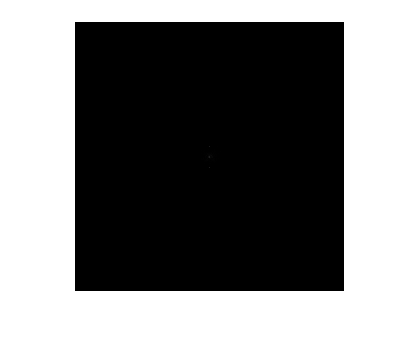

figure;
imshow(magnitude_spectrum, []);

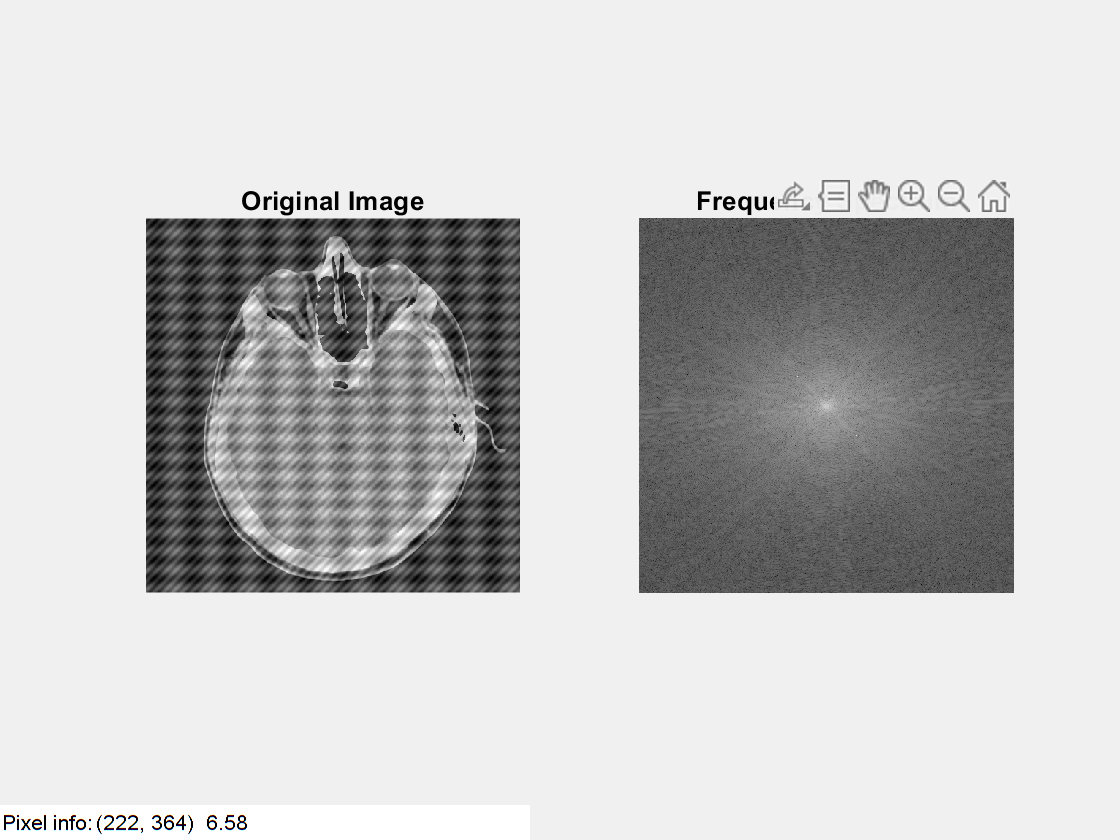

impixelinfo  

band rejector

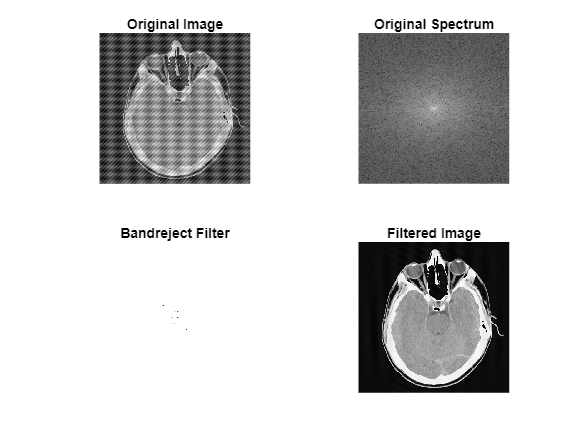

% Create the bandreject filter
[M, N] = size(img);
[X, Y] = meshgrid(1:N, 1:M);
center_x = 257;
center_y = 257;

% Define noise points (excluding the center point)
noise_points = [
    217, 217;   % Point 1
    297, 297;   % Point 2
    267, 237;   % Point 3
    247, 257;   % Point 4
    267, 257;   % Point 5
    257, 277;   % Point 6
    297, 297    % Point 7
];

% Create the notch filter
H = ones(M, N);
D0 = 1;  % Width of the reject band 

% Apply notch for each noise point and its symmetric point
for i = 1:size(noise_points, 1)
    x = noise_points(i,1);
    y = noise_points(i,2);
    
    % Distance from current point
    D1 = sqrt((X - x).^2 + (Y - y).^2);
    
    % Calculate symmetric point coordinates
    x_sym = 2*center_x - x;
    y_sym = 2*center_y - y;
    
    % Distance from symmetric point
    D2 = sqrt((X - x_sym).^2 + (Y - y_sym).^2);
    
    % Create notch for both points
    H = H .* (1 - exp(-D1.^2/(2*D0^2))) .* (1 - exp(-D2.^2/(2*D0^2)));
end

% Apply the filter
filtered_spectrum = f_shift .* H;

% Inverse FFT to get filtered image
filtered_image = real(ifft2(ifftshift(filtered_spectrum)));

% Display results
figure;
subplot(2,2,1);
imshow(img, []);
title('Original Image');

subplot(2,2,2);
imshow(log(1 + abs(f_shift)), []);
title('Original Spectrum');

subplot(2,2,3);
imshow(H, []);
title('Bandreject Filter');

subplot(2,2,4);
imshow(filtered_image, []);
title('Filtered Image');

band pass

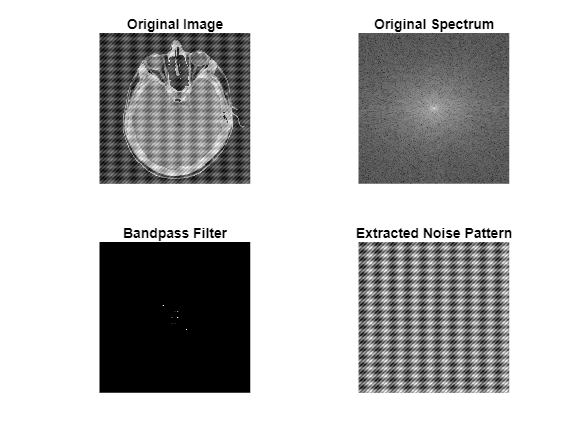

% Create the bandpass filter (opposite of bandreject)
[M, N] = size(img);
[X, Y] = meshgrid(1:N, 1:M);
center_x = 257;
center_y = 257;

% Define noise points (excluding the center point)
noise_points = [
    217, 217;   % Point 1
    297, 297;   % Point 2
    267, 237;   % Point 3
    247, 257;   % Point 4
    267, 257;   % Point 5
    257, 277;   % Point 6
    297, 297    % Point 7
];

% Create the bandpass filter (H_bp = 1 - H_br)
H = zeros(M, N); 
D0 = 1; 

% Apply pass band for each noise point and its symmetric point
for i = 1:size(noise_points, 1)
    x = noise_points(i,1);
    y = noise_points(i,2);
    
    % Distance from current point
    D1 = sqrt((X - x).^2 + (Y - y).^2);
    
    % Calculate symmetric point coordinates
    x_sym = 2*center_x - x;
    y_sym = 2*center_y - y;
    
    % Distance from symmetric point
    D2 = sqrt((X - x_sym).^2 + (Y - y_sym).^2);
    
    % Create pass band for both points
    H = H + exp(-D1.^2/(2*D0^2)) + exp(-D2.^2/(2*D0^2));
end

% Clip filter values to range [0,1]
H = min(H, 1);

% Apply the filter
filtered_spectrum = f_shift .* H;

% Inverse FFT to get noise pattern
noise_pattern = real(ifft2(ifftshift(filtered_spectrum)));

% Display results
figure;
subplot(2,2,1);
imshow(img, []);
title('Original Image');

subplot(2,2,2);
imshow(log(1 + abs(f_shift)), []);
title('Original Spectrum');

subplot(2,2,3);
imshow(H, []);
title('Bandpass Filter');

subplot(2,2,4);
imshow(noise_pattern, []);
title('Extracted Noise Pattern');